# Robotics and Control 2  -  Project

clc
clear

## Definition of Scenario (Trajectory to be tracked and position of the box)

As first phase it is asked to define the scenario with the choice and characterization of the path and position of the box

% --- 1. Setup Environment ---
% 1=Wall, 0=Path
Maze = [
    1 1 1 1 1 1 1 1;
    1 0 0 0 0 0 0 1;
    1 0 1 1 1 1 0 1;
    1 0 0 0 0 1 0 1;
    1 1 1 1 1 1 1 1
];

% --- Define Colors ---
% Define the RGB vectors (R, G, B) where values are between 0 and 1.
PathColor = [0 0 0];          % Black (Dark Background)
WallColor = [0 0.5 1];        % Neon Blue

% Colormap definition: Ordered by matrix values 0 and 1
CustomMap = [PathColor; WallColor];

% Visualization
figure(1);
clf; % Clear the figure for a clean start

% 1. Set the FIGURE background color (the window border/outside area)
set(gcf, 'Color', PathColor);

% 2. Set the AXES background color (the plotting area)
% Note: gca gets the current axes handle.
set(gca, 'Color', PathColor); 

hold on; % Hold on to allow drawing walls and paths

% --- 4. Visualize the Maze with imagesc ---

imagesc(Maze);
colormap(CustomMap);

% Set the color limits to map values 0 and 1 to the two colors
clim([0 1]); 

axis equal;    % Ensures cells are square
axis off;      % Removes axis ticks and labels
hold on; % Important! Allows us to draw over the maze

% --- Define the Path ---
% Ideally, this comes from a pathfinding algorithm (like BFS or A*).
% For now, we will manually define a path for the agent to follow.
% Format: [Row, Column]
PathList = [
    2, 2; % Start
    2, 3;
    2, 4;
    2, 5;
    2, 6;
    2, 7;
    3, 7;
    4, 7;
    4, 6; % End
];

% ---  Initialize the Agent ---
% We create the agent at the first position of the path.
startPos = PathList(1, :);

% Draw the Agent (Red Square)
% Note: We save the graphics handle 'hAgent' to update it later.
hAgent = plot(startPos(2), startPos(1), 'rs', ...
    'MarkerSize', 20, 'MarkerFaceColor', 'r');

% Draw the Path Line (The "Red Wire" from your image)
% We swap columns/rows for plotting because plot(x,y) uses x=col, y=row
plot(PathList(:,2), PathList(:,1), 'r-', 'LineWidth', 2);

% --- 4. The Movement Loop ---
disp('Agent starting movement...');

Agent starting movement...


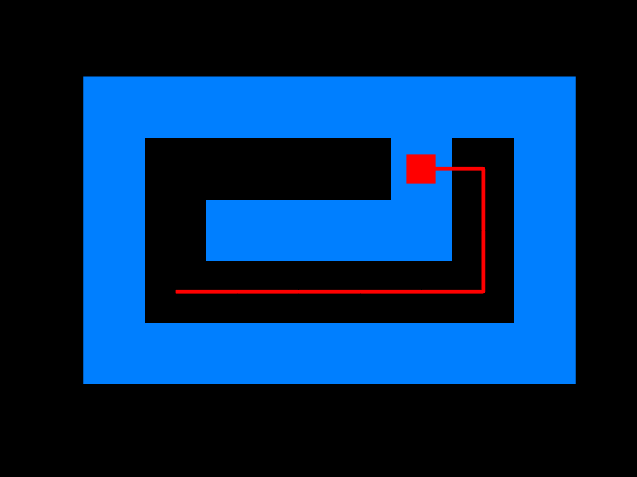

pause(1); % Wait a second before starting

for i = 1:size(PathList, 1)
    % Get the next coordinate from the list
    currentRow = PathList(i, 1);
    currentCol = PathList(i, 2);
    
    % --- CORE MOVEMENT LOGIC ---
    % Instead of clearing and redrawing the whole figure, 
    % we just update the X and Y data of the agent handle.
    % This is much faster and smoother.
    set(hAgent, 'XData', currentCol, 'YData', currentRow);
    
    % Force MATLAB to update the screen immediately
    drawnow; 
    
    % Control the speed (0.2 seconds per step)
    pause(0.2); 
end


disp('Destination reached!');

Destination reached!
